syl = ret.syllables.Syllable;
orig = ret.syllables.OriginalImage;

% rootFolder = 'E:\Itzik\itzik 25072021\Itzik\images_128_lowerTH';
% sylDir = fullfile(rootFolder,'syllables_clean');
% originalDir = fullfile(rootFolder,'syllables_original');
%
% imdsSyl = imageDatastore(sylDir, ...
%     'IncludeSubfolders',true, ...
%     'LabelSource','foldernames');
%
%
% imdsOrig = imageDatastore(originalDir, ...
%     'IncludeSubfolders',true, ...
%     'LabelSource','foldernames');
%
%
% numImagesToRead = 100;
% imdsSyl.ReadSize = numImagesToRead;
% syl = imdsSyl.read;
% imdsOrig.ReadSize = numImagesToRead;
% orig = imdsOrig.read;
%
% syl = cellfun(@flipud,syl,'UniformOutput',false);
%
% orig = cellfun(@flipud,orig,'UniformOutput',false);


syl = cellfun(@mat2gray,syl,'UniformOutput',false);

orig = cellfun(@mat2gray,orig,'UniformOutput',false);


numImges= 79;
% sz = size(syl,1);
% ind = datasample(1:sz,numImges,'Replace',false);

from = 0;
ind = (1:numImges)+from;
ksyl = syl(ind);
ksyl = CropAndPadMatrix(ksyl,128,128,"min");
korig = orig(ind);
korig = CropAndPadMatrix(korig,128,128,"min");

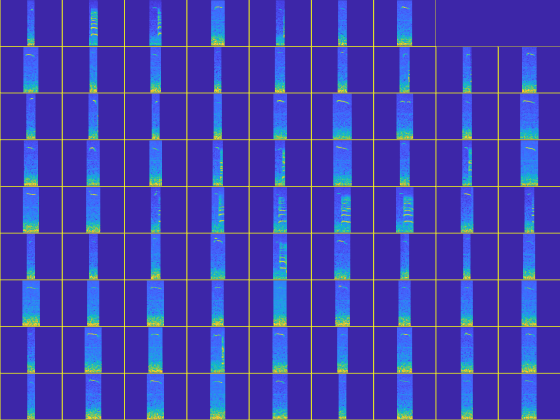

%1 original
%2 raw syllable
%3 binarized syllable
%4 reconstructed syllable
korigPlot = plotK(korig);

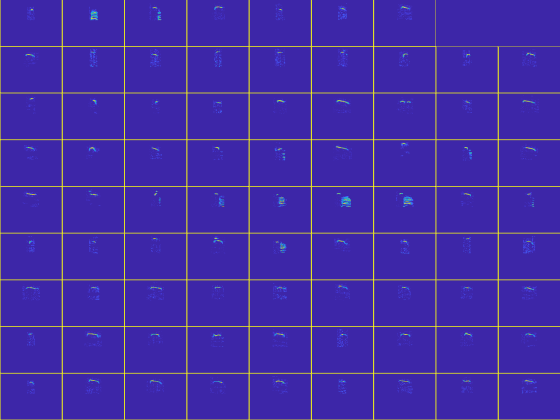



ksylPlot = plotK(ksyl);

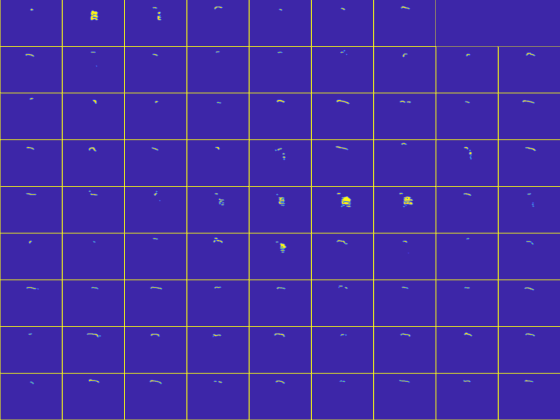

prepSyl = prepareSyl(ksyl);
prepSylPlot = plotK(prepSyl);

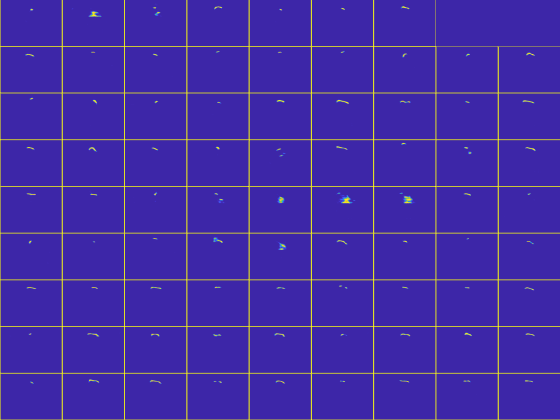

[predSyl,encodedVecs] = predictK(prepSyl,encoder_decoder);
% predSyl= double(predSyl>0.1);

predSylPlot = plotK(squeeze(predSyl),1);

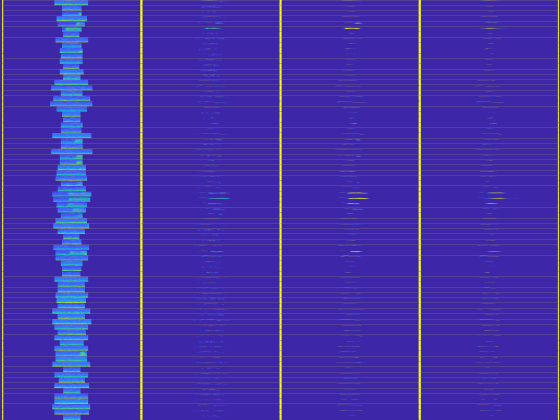

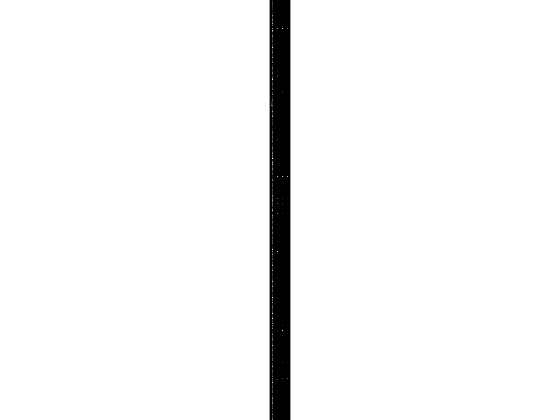


allK = cat(2,korigPlot,ksylPlot,prepSylPlot,predSylPlot);
% allK = cat(2,korigPlot,ksylPlot,predSylPlot);
% allK = cat(2,korigPlot,ksylPlot,prepSylPlot);
allKPlot = plotSideByside(allK,1);

function k = prepareSyl(k)
numImges = size(k,3);
for i = 1:numImges
    %     tempK = flipud(double(squeeze(k(:,:,i))));
    tempK = double(squeeze(k(:,:,i)));
    tempK = medfilt2(tempK,[3 3]);


    %     % %
    %         T = adaptthresh(tempK,0.9,'NeighborhoodSize',[15 15]);
    %         tempK = imbinarize(tempK,T);
    %         tempK = imbinarize(tempK,'global');
    %
    tempK = imbinarize(tempK,0.20);
    tempK = imbilatfilt(double(tempK),1,1);


    % ksize = 3;
    % [~,indtempK] = maxk(tempK,ksize,1);
    %     indtempK(indtempK<40) = nan;
    %     tempK = zeros(size(tempK));
    %     ind = sub2ind([128,128],indtempK,repmat(1:128,[ksize,1]));
    %     ind(isnan(ind)) = [];
    %     if ~isempty(ind)
    %         tempK(ind) = 1;
    %     end

    k(:,:,i) = single(tempK);
end
end
function [k,imgesRaw] =  plotK(k,flipflag)
if ~exist('flipflag','var')||isempty(flipflag)
    flipflag = false;
end
numImges = size(k,3);
for i = 1:numImges
    k(:,1,i) = 1;
    k(:,end,i) = 1;
    k(1,:,i) = 1;
    k(end,:,i) = 1;
    if flipflag
        k(:,:,i) = flipud(k(:,:,i));
    end
end
imgesRaw = imtile(k);

figure

surface((imgesRaw),'EdgeColor','none')
axis tight
ax = gca;
ax.Position = [0 0 1 1];
end
function [k,encodedVectors] = predictK(k,net)
for i = 1:size(k,3)
    k(:,:,i) = flipud(k(:,:,i));
end
k = permute(k,[1,2,4,3]);
encodedVectors = activations(net,k,'fc_2');
k = predict(net,k);
end

function imgesRaw = plotSideByside(k,nrows)
if ~exist('nrows','var')||isempty(nrows)
    nrows = 2;
end
imgesRaw = imtile(k,'GridSize',[nan, nrows],"BorderSize",[2 2]);
figure
surface((imgesRaw),'EdgeColor','none')
axis tight
ax = gca;
ax.Position = [0 0 1 1];
f = figure;
% f.Position =[2317,50,221,885];
ax = gca;
ax.Position = [0 0 1 1];
imshow(flipud(imgesRaw))
end
